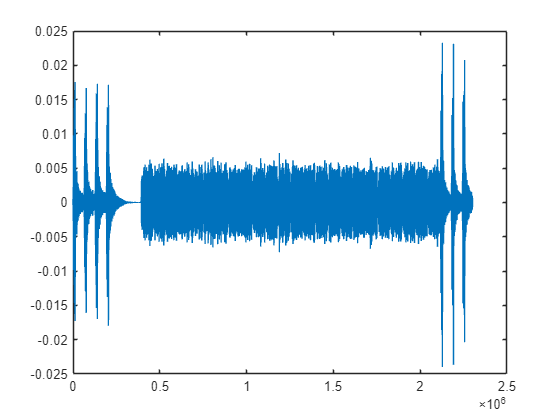

K = 2048;
L = 200;
Fc = 24000;
B = 8000;
W = 24;
Lambda = 24;
Sampler = 256000;
vel = 1.03;
c = 1500;
%a = vel/c;
%%% Step 0 Load the .mat files
load("test_rece_data_173048_1472.mat");
load("pilot_signal_for_synchronization.mat");
load("ofdm_map.mat");
load("benchmark_parameter_174623_1472.mat");
load("benchmark_rece_data_174623_1472.mat");
load("benchmark_Zw_174623_1472.mat");
load("itc_1007_compfilter.mat");
%%% Step 1: PB filter to remove noise beyond PB
y_in = rece_data_ofdm_test; %load benchmark_rece_data_174623_1472.mat
%ypb = zeros(length(y_in), 1);
y_pb = bandpass(y_in, [-4000+Fc, 4000+Fc], Sampler);
plot(y_pb);


%%% Step 2: Estimate a
T_tx = 8269.52; %In ms
T_txs = T_tx / 1000; %In sec
sr = 1 / Sampler; %Sampling rate in seconds
T_rx_est = 2115617 * sr; %Estimated Trx duration in sec 2117460 
a_est = (T_txs/T_rx_est)-1 % The minus 1 was missing before

a_est = 6.5235e-04

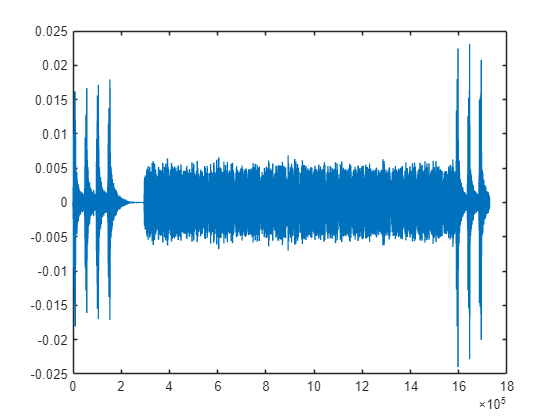

%%a_est = a_est_174623; %TA's given a_hat value, load benchmark_parameter_174623_1472.mat

%%% Step 3: Resampling
%y_pb_re = resample(y_pb, round((1+a)*1*exp(5)), round(1*exp(5))); %%% Double check with TA
y_pb_re = resample(y_pb, round((1+a_est)*1e5), 1e5);

%%% Step 4: Resampling from 256k to 192k
Ls = 192;
Ms = 256;
Lp = 24;
N = Lp*Ls-1;
h = Ls*fir1(N, 1/Ms, kaiser(N+1, 7.8562));
Ytilda_pb_re = upfirdn(y_pb_re, h, Ls, Ms);
plot(Ytilda_pb_re);

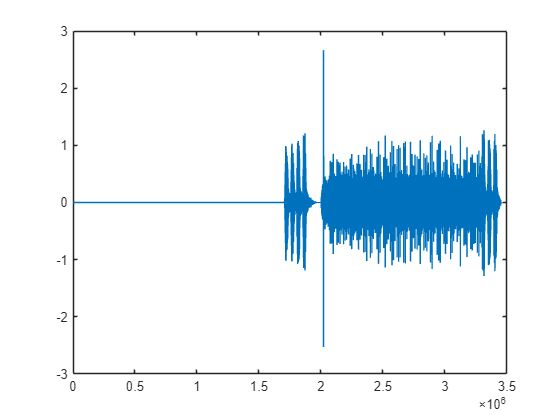

%freqz(Ytilda_pb_re, 1);

%%% Step 5: Synchronization
pilot = OFDM_data_pre_old; %load pilot_signal_for_syncronizaation.mat
%plot(pilot);

correlate = xcorr(Ytilda_pb_re, pilot); % Correlation with pilot signal
plot(correlate);

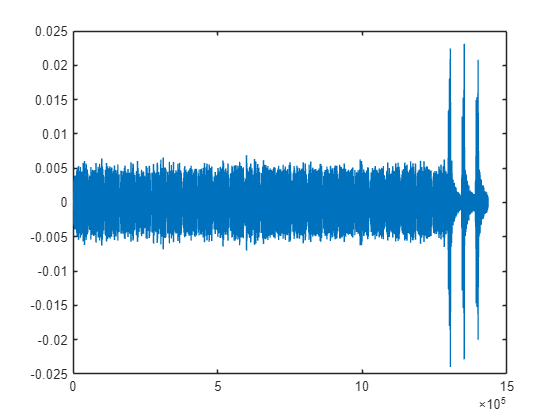


i = max(correlate); % Finds max value index for n_0
for j = 1:length(correlate)
    if i == correlate(j)
        n_0 = j - length(Ytilda_pb_re);
    end
end

Ytilda_n0 = Ytilda_pb_re(n_0:end);    % Truncates signal to start at n_0
plot(Ytilda_n0)

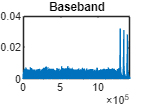


%%% Step 6 Convolution for PB -> BB
Ytilda_conv = conv(Ytilda_n0, h_comp); % Convolution with 101 sample vector
%plot(Ytilda_conv)
Ytilda_no_delay = Ytilda_conv(51:end); % Cut out first 50 data points of delay

%%% Step 7 PB -> BB
Sampler = 192000;
Y_BB_I = zeros(1, length(Ytilda_no_delay)); % Preallocate arrays for processing speed
Y_BB_Q = zeros(1, length(Ytilda_no_delay));
Y_BB = zeros(1, length(Ytilda_no_delay));
for n = 1:length(Ytilda_no_delay)   % As seen in handout
Y_BB_I(n) = Ytilda_no_delay(n)*2*cos(2*pi*Fc*n*1/Sampler);
Y_BB_Q(n) = -Ytilda_no_delay(n)*2*sin(2*pi*Fc*n*1/Sampler);
Y_BB(n) = Y_BB_I(n) + 1i*Y_BB_Q(n);
end
%plot(Y_BB)

%%% Step 8 Raised Cosine Convolution
beta = .125; % roll-off factor
Fs = 192000; % sampling frequency
Fd = 8000; % data/transfer rate
lamda_oversamp = Fs/Fd; % lambda = 24 defined above works too
delay = 100;    % Given delay in part 1 before oversampling
span = 2*delay;
Rn = rcosdesign(beta, span, Fs/Fd, 'sqrt'); % rcosine filter (similar to sinc function)
%plot(Rn)
plot(abs(Y_BB));    % Checking signal before filtering
title("Baseband");

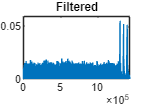

Y_BB_filtered = conv(Y_BB, Rn); % Same as part 1 Step 5
plot(abs(Y_BB_filtered))    % Checking signal after filtering
title("Filtered");

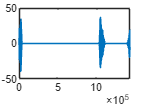

plot(real(fft(Y_BB)))

delay_os = length(Y_BB_filtered)-length(Y_BB)   % Delay obtained by difference of signal lengths 

delay_os = 4800

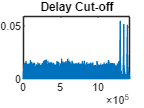

Y_BB_no_delay = Y_BB_filtered(delay_os/2+1:length(Y_BB_filtered)-delay_os/2);   % Cuts out delay
plot(abs(Y_BB_no_delay));   % Should be the same length as Y_BB
title("Delay Cut-off");



%%% Step 9 Grid Search
Ts = 1/Fs;
zp_up = (K+L)*Lambda; %For loop sizes (no minus 1 because 1-indexing)
zp_down = K+L;

% Preallocation of matrices and counters
Y_BB_down = zeros(zp_down, 1);
Z_1 = zeros(zp_down,1);
i = 1:zp_down;
m = (1:2248);
m = transpose(m);
count = 1;
P_NULL = zeros(8241, 1);    % length n_0 x epsilon, 201x41
fft_matrix = exp((-1i*2*pi*(m-1)*(i-1))/K); % FFT
z_count = 1;

    % Null Carriers Step
ofdm = transpose(ofdm_map)

ofdm =      1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2


min_OFDM = zeros(zp_down, 1);
for k = 1:K
    if ofdm_map(k, 1) == 0
        min_OFDM(k, 1) = 1;
    end
end

    % Obtain First OFDM Data
for n_0_1 = 2200:1:2400  % n_0,1
    for epsilon_1 = -2:0.1:2 
        n_idx=n_0_1+(0:Lambda:zp_down*Lambda-1);   % CFO Compensation with downsampling
        Y_BB_down(:, 1) = Y_BB_no_delay(n_idx).*exp(-1i*2*pi*epsilon_1*n_idx*Ts);
        Z_1 =  fft_matrix*Y_BB_down;
        %Z_1 = Z_1(1:K, 1);
        P_NULL(count, 1) = sum(Z_1.*conj(Z_1).*min_OFDM);
        count = count + 1;
    end
end
P_NULL_min = min(P_NULL);
P_NULL = reshape(P_NULL, 41, 201);
for o = 1:201
    for p = 1:41
        if P_NULL(p, o) == P_NULL_min
            %o_idx = o
            %p_idx = p
            n_0_1 = o+2199;
            epsilon_1 = p*.1-2.1;
            break
        end
    end
end

% P_null_min = min(P_null);
% for o = 1:length(P_null)
%     if P_null(o, 1) == P_null_min
%         idx_t = o;
%         n_0_1_t = round(idx_t/40+2199);
%         epsilon_1_t = mod(idx_t+40, 40)*.1-2.1;
%     end
% end

Z_1 = Z_1(round(n_0_1/Lambda):end, 1); % Obtain frequency domain data here

Z_all = zeros(zp_down, W-3);
Z_all(1:length(Z_1), 1) = Z_1(1:length(Z_1), 1);

n_all = zeros(W-3, 1);
epsilon_all = zeros(W-3, 1);

n_all(1, 1) = n_0_1;
epsilon_all(1, 1) = epsilon_1;

%%% Step 10
n_0_w_1 = n_0_1;
Z_w = zeros(zp_down,1);

for w = 1:20
    P_NULL = zeros(3977, 1);    % length n_0 x epsilon, 97x41
    count = 1;
    z_count = z_count+1;
    for n_0_w = n_0_w_1 + zp_up + (-2*Lambda:1:2*Lambda)  % Grid Search foor loop
        % n_count = n_count + 1;
        for epsilon_w = -2:0.1:2
            n_idx=n_0_w+ (1:Lambda:zp_down*Lambda);   % CFO Compensation with downsampling
            Y_BB_down(:, 1) = Y_BB_no_delay(n_idx).*exp(-1i*2*pi*epsilon_w*n_idx*Ts);
            Z_w =  fft_matrix*Y_BB_down;
            %Z_w = Z_w(1:K, 1);
            P_NULL(count, 1) = sum(Z_w.*conj(Z_w).*min_OFDM);
            count = count + 1;
        end
    end
    P_NULL_min = min(P_NULL);   % Min P_null
    P_NULL = reshape(P_NULL, 41, 97);
    for o = 1:97
        for p = 1:41
            if P_NULL(p, o) == P_NULL_min
                o_idx = o;
                p_idx = p;
                n_0_w = n_0_w_1+zp_up+o-2*Lambda-1;
                epsilon_w = p*.1-2.1;
                break
            end
        end
    end
    %Z_w = Z_w(round(n_0_w/Lambda):end, 1); % Obtain frequency domain data here
    Z_all(1:end, z_count) = Z_w(1:end, 1);
    n_all(z_count, 1) = n_0_w;
    epsilon_all(z_count, 1) = epsilon_w;
    n_0_w_1 = n_0_w;
end